# Two-Train Analysis

**Author**: Michel Barbeau

**Version**: September 13, 2021

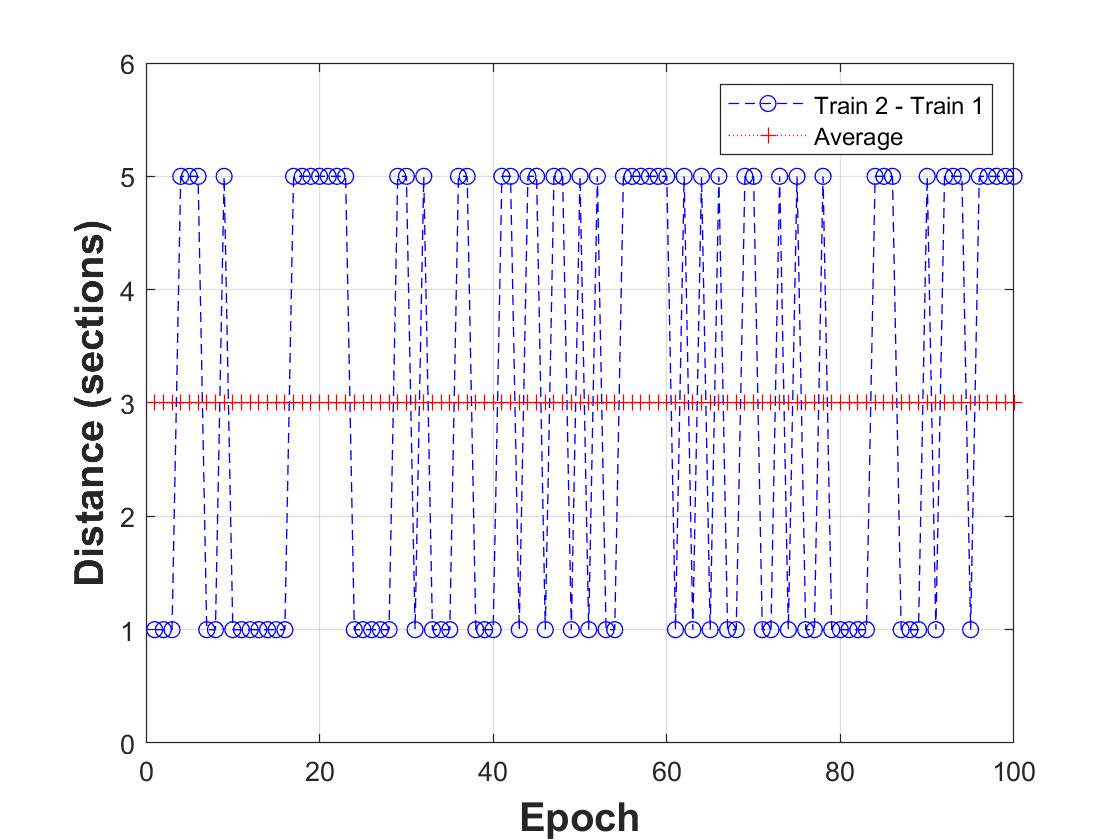

clear;
% Relative distance, in sections 
dx = [5 5 5 5 5 1 1 1 1 1];
% Generate n random integers in 1..4 range
n = 100;
r = randi([1 10],1,n);
%%%% plot the distances
%% Nominal case
figure;
plot(1:n,dx(r),'b--o');
hold on;
a = mean(dx(r));
plot(1:n,a*ones(size(dx(r))),'r:+');
% title('Nominal case');
xl = xlabel('Epoch');
set(xl, 'FontSize', 15,'fontweight','bold');
yl = ylabel('Distance (sections)');
set(yl, 'FontSize', 15,'fontweight','bold');
yticks([0 1 2 3 4 5 6]);
ylim([0 6])
grid on;
leg = legend("Train 2 - Train 1","Average");

%title(leg,'');

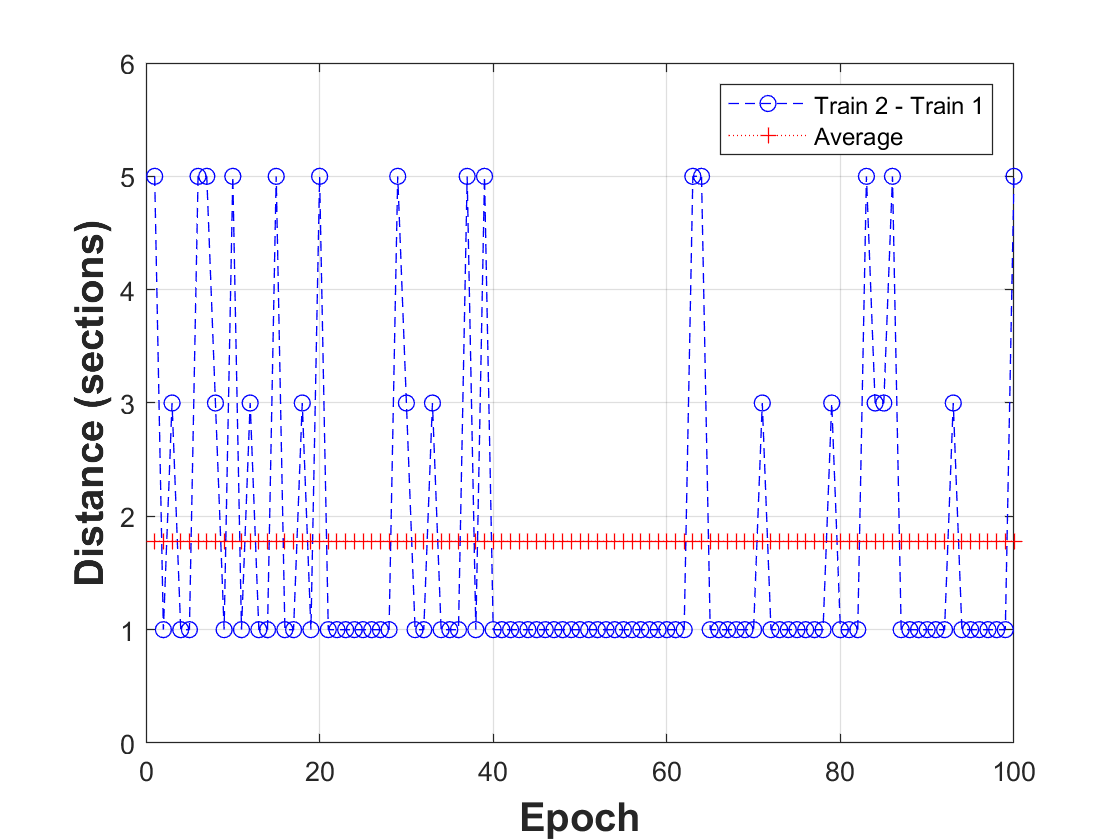

% Attack case, adversary learned the behavior of agent, high
% probability of doing the same
% Relative distance, in sections 
dx = [1 1 1 1 1 1 1 1 5 3];
% Generate n random integers in 1..4 range
n = 100;
r = randi([1 10],1,n);
%%%% plot the distances
%% Nominal case
figure;
plot(1:n,dx(r),'b--o');
hold on;
a = mean(dx(r));
plot(1:n,a*ones(size(dx(r))),'r:+');
% title('Nominal case');
xl = xlabel('Epoch');
set(xl, 'FontSize', 15,'fontweight','bold');
yl = ylabel('Distance (sections)');
set(yl, 'FontSize', 15,'fontweight','bold');
yticks([0 1 2 3 4 5 6]);
ylim([0 6])
grid on;
leg = legend("Train 2 - Train 1","Average");